# Calculate marginal cost

Firstly, make sure you are in the ***model_code*** directory. The output files should written into ***model_output*** directory.

## Import selected datetime and price

load selDateTimePriceISONE.mat;
selDateTimes = selDateTimePrice.DateTime;
selDates = datetime(year(selDateTimes), month(selDateTimes), day(selDateTimes), "Format","MM/dd/uuuu");
selHours = hour(selDateTimes);
numSelDateTimes = size(selDateTimes, 1);

% Specify number of datetimes for calculation
startDateTime = 1000;
endDateTime = 1010;
calDateTime = [startDateTime:endDateTime]';
numCalDateTime = size(calDateTime, 1);
selDateTimes(startDateTime: endDateTime);

## Import ISONE hourly demand data

% Import hourly generation data of generators in RGGI database in the 2019 whole year
% Run this under the model_code directory or change the genFileDir manually
demandFileDir = "..\data\2019_DEMAND_ISONE\";
demandFileName = "da_hourlydemand_2019*.csv";
demandDataStore = fileDatastore(demandFileDir + demandFileName, "ReadFcn", @importDemandISONE, "UniformRead", true);
demandAll = readall(demandDataStore);
clear demandDataStore;

## Calculate marginal cost of top market participants at selected hours

topQuantMCTables = cell(numCalDateTime, 1);
clearingPricesED = zeros(numCalDateTime, 1);
numTopParts = 10;
tic
% Using Parallel computing to loop through all the selected hours
for m = 1:numCalDateTime
    dt = calDateTime(m);
    selDate = selDates(dt);
    selHour = selHours(dt);
    % Obtain market clearing price from ISONE database
    marketClearingPrice = selDateTimePrice(dt, :).averageLMP;
    % Obtain total demand at the selected hour
    hourlyDemand = demandAll(demandAll.Date == selDate, :);    
    selHourDemand = hourlyDemand(hourlyDemand.Hour == selHour, :).DayAheadDemand;
    % Calculate marginal cost of top market participants at selected hour
    [topQuantityMC, clearingPrice] = hourlyQuantityMC(selDate, selHour, numTopParts, marketClearingPrice, selHourDemand);
    topQuantMCTables{m} = topQuantityMC;
    clearingPricesED(m) = clearingPrice;
    fprintf("Success: loop No. %d, hour No. %d, %s %d:00\n", m, dt, selDate, selHour);
end

Success: loop No. 1, hour No. 1000, 03/22/2019 2:00
Success: loop No. 2, hour No. 1001, 03/22/2019 3:00
Success: loop No. 3, hour No. 1002, 03/22/2019 4:00
Success: loop No. 4, hour No. 1003, 03/22/2019 5:00
Success: loop No. 5, hour No. 1004, 03/22/2019 6:00
Success: loop No. 6, hour No. 1005, 03/22/2019 7:00
Success: loop No. 7, hour No. 1006, 03/22/2019 8:00
Success: loop No. 8, hour No. 1007, 03/22/2019 9:00
Success: loop No. 9, hour No. 1008, 03/22/2019 10:00
Success: loop No. 10, hour No. 1009, 03/22/2019 11:00
Success: loop No. 11, hour No. 1010, 03/22/2019 12:00


toc

Elapsed time is 940.515351 seconds.


## Summarize marginal cost results and write to a file

topQuantMCSummary = topQuantMCTables{1};
for m = 2:numCalDateTime
    topQuantMCSummary = vertcat(topQuantMCSummary, topQuantMCTables{m});
end
topQuantMCSummary

topQuantMCSummary = 110×6 table
       Date       Hour    PartID    Awarded    MCSimpleED    MCMarket
    __________    ____    ______    _______    __________    ________

    03/22/2019     2      401592      2129       21.764       16.333 
    03/22/2019     2      591975      1784        21.75       11.482 
    03/22/2019     2      206845      1284       22.965       18.658 
    03/22/2019     2      749668       860       23.428       19.554 
    03/22/2019     2      902793       701       23.574       19.809 
    03/22/2019     2      219842       680       23.824       20.319 
    03/22/2019     2      595644       578       23.675       20.428 
    03/22/2019     2      212494     317.5        24.33       21.304 
    03/22/2019     2      975156       207       24.496       2

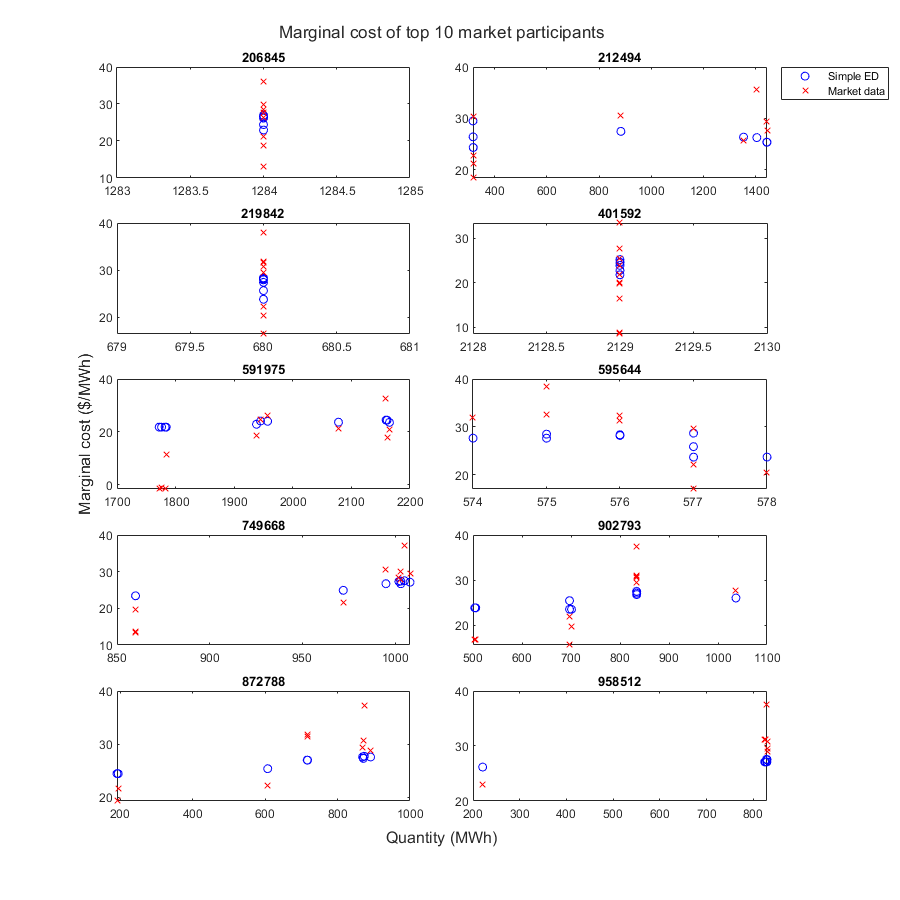

% You have to run this under model_code directory
MCOutFileDir = "../model_output/";
MCOutFileName = sprintf("MC_%d_%d.csv", startDateTime, endDateTime);
writetable(topQuantMCSummary, MCOutFileDir+MCOutFileName);